# Motivation for multi-phase flows

There is more to life than single-phase flow. Many fluid dynamics applications require understanding the interaction between multiple phases of fluids. Such applications include heat transfer with phase change, jet fuel atomization, surfactant replacement therapy, and many more. However, the challenge for most schemes is accurately defining the fluid interface, performing interface advection and preserving/capturing sharp changes in that interface. Like the flow solver implementation, there exist a plethora of methods, all of which have pros and cons. Some methods of interface tracking are the marker-and-cell method and front tracking. Another approach is interface capturing; these methods include volume-of-fluid, level set, phase field and constrained interpolation profile. Each one of these has its own subset of methods for implementation as well. In this teaching module, you will learn the fundamentals of the **volume-of-fluid method.**

### **Learning Objectives**

- Understand geometry initialization using VOF

- Solving the transport equation

- Learn geometric flux calculation using SLIC

### Volume-of-fluid method (VOF)

In an ideal world, the fluid interface would be represented exactly, and the velocity field could exactly advect the interface each time step. The trade-off for such accuracy is an increase in computational cost, requiring more resources to run the schemes and time to compute. The VOF method is an approach to interface-capturing which does not exactly track the location of the interface. Instead, a color function $f$ is defined to indicate whether that location in the field is within the reference fluid, essentially capturing the interface.


$$f(\vec{x})  = \begin{cases} 1 \vec{x} \in \text{fluid} 1\\ 0 \vec{x} \notin \text{fluid} 1\end{cases}$$


A volume fraction $F$ is then defined to be the fraction of cell volume $V$ which contains $fluid 1$:


$$F = \frac{1}{V} \int_V f dV$$


If a computational cell is completely filled, its volume fraction $F = 1.0$; if the cell is half filled, $F = 0.5$.

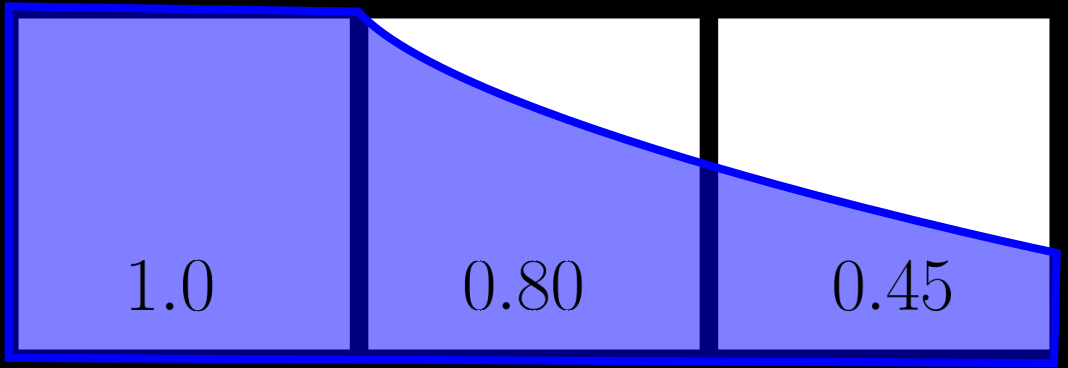

To advect the fluid interface the following transport equation is solved:


$$\frac{\partial f}{\partial t} + \nabla \cdot (\vec{U} f) = 0$$



$$f_{j, i}^{n+1} = f_{j, i}^n - \Delta t \frac{u_{j,i+1}f _{j, i}^n - u_{j, i}f_{j,i-1}^n}{\Delta x}$$


However, simply following the above equation will yield an unstable solution and smear the interface. Generally, the transport equation is not written in that form because of its misleading nature. Instead, the transport equation is written as equation $(\mathcal{T})$:


$$f_{j, i}^{n+1} = f_{j, i}^n - \frac{F_R - F_L}{\Delta x}$$
      
$$(\mathcal{T})$$


where $F_R$ and $F_L$ are the right and left fluxes at the cell faces, but the question remains: **how are those fluxes computed? **Well, the amount of fluid being advected into the right face is contained within the red box, which has a width of $u \Delta t$. The challenge is coming up with an expression or algorithm to determine exactly what amount of fluid is contained in the red box. 

 Remember, all we know is the volume fraction of fluid contained within the cell. The interface shown here is not explicitly known(the exact interface is drawn for reference). If the location and construction of the interface were known, computing the flux would then be possible.

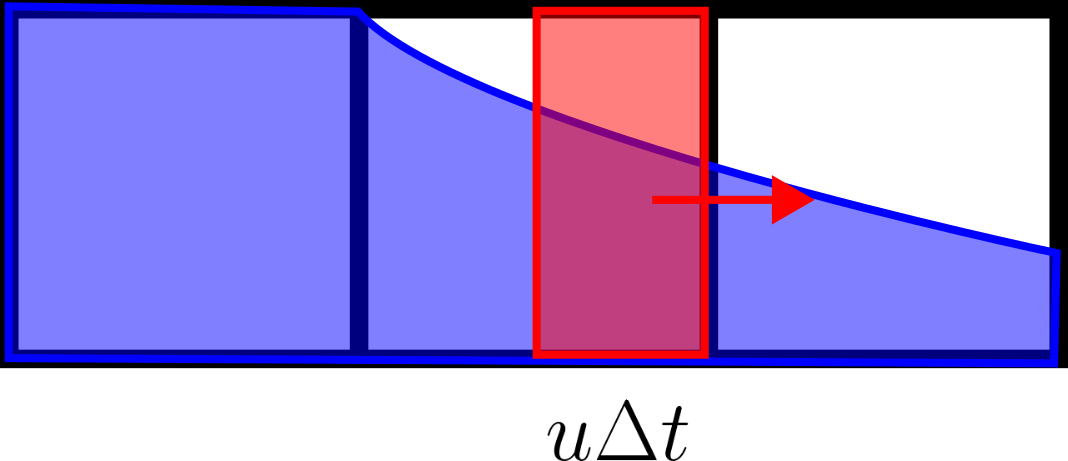

#### Simple line interface calculation(SLIC)

One of the first and most cited interface reconstruction schemes for volume advection is the [SLIC method](https://link.springer.com/chapter/10.1007/3-540-08004-X_336). In this method, the interface is reconstructed and represented as a single line, parallel to one of the coordinate directions.

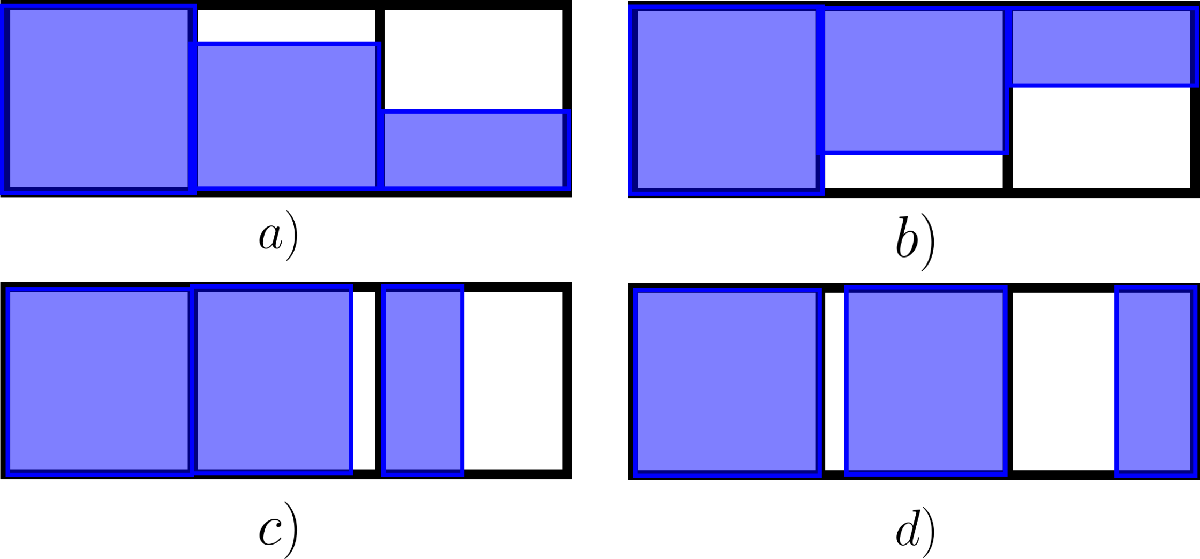

As you can see, it does not exactly fit the true interface, but approximates the interface's location. Much like other schemes, there are many methods for [implementing SLIC](https://www.ljll.math.upmc.fr/~frey/papers/levelsets/Rudman%20M.,%20Volume%20tracking%20methods%20for%20interfacial%20flows%20calculations.pdf). Images a), b), c) and d) illustrate four possible interface approximations. In this case, it appears image a) best reconstructs the interface geometry. Much like the original publication, we offer no exact implementation for the scheme. However, in the next section, we will intuitively derive a possible method for computing the fluxes using the SLIC method for geometric reconstruction. By no means is this derivation the best approach. The purpose of the derivation is to help the user develop an intuition for geometric reconstruction. 

### Geometry generation

How do we generate a volume fraction field for a fluid droplet with a radius $r$, with a center at $(xCent, yCent)$? Well, in the image below, we can see the exact interface.

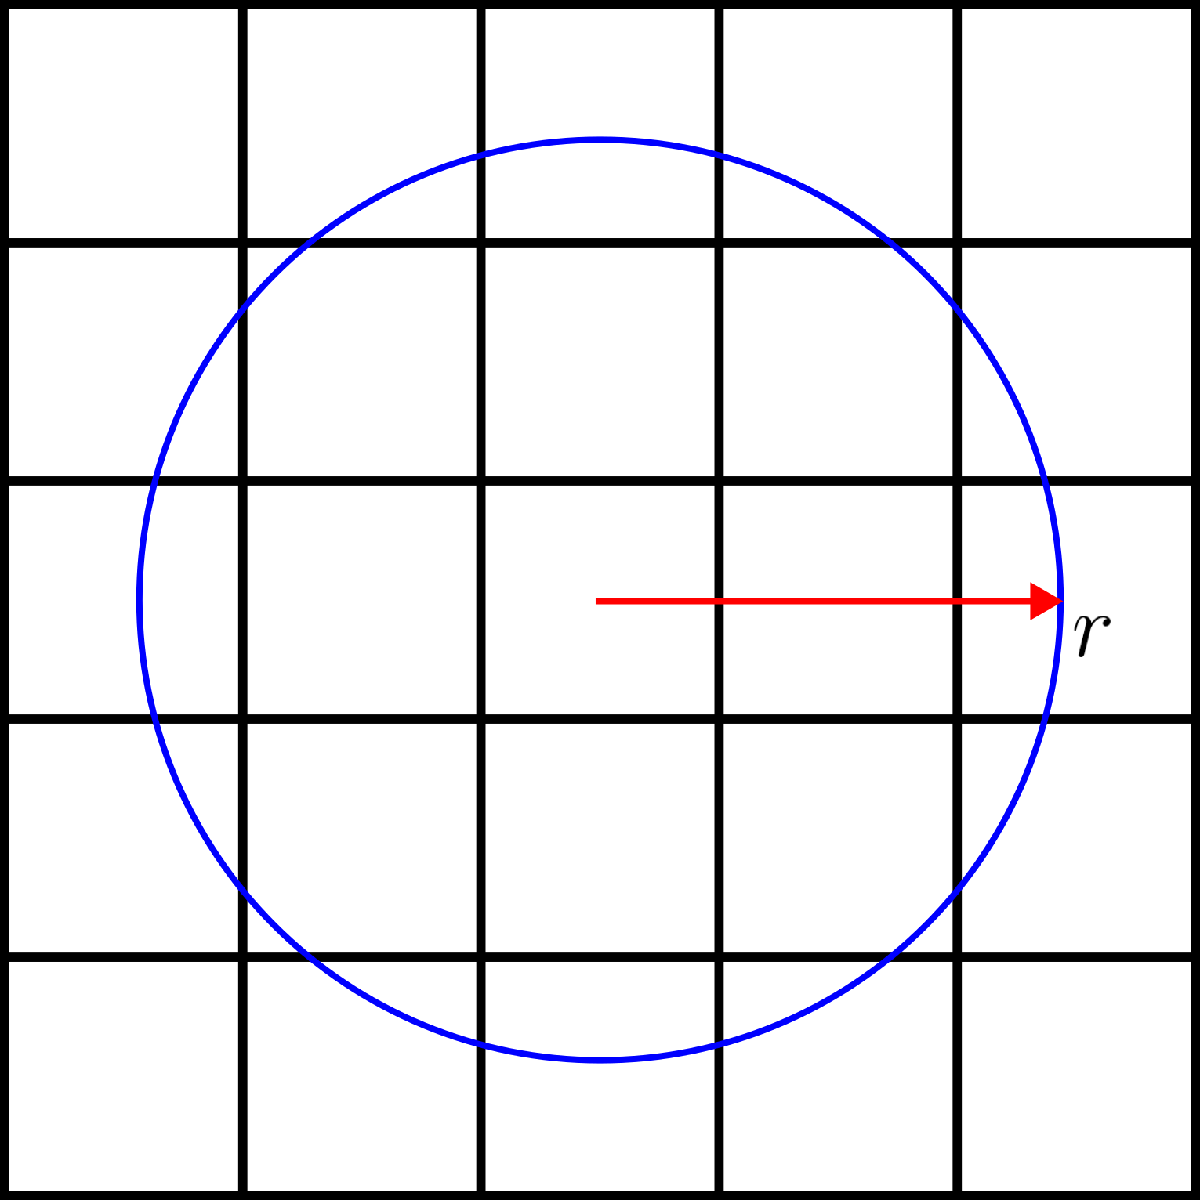

A circle centered in the domain will have coordinates that fit within equation $(\mathcal{a})$:


$$(x - xCent)^2 + (y-yCent)^2 \leq r^2$$
      
$$(\mathcal{a})$$


To determine if a cell has a volume fraction $f = 1.0$, all of the cell's vertices(**image e)** must satisfy equation $(\mathcal{a})$, else if all of the cell's vertices(**image f) **are greater than the square of the radius, the volume fraction $f = 0.0$. If neither are true(**image g)**, this is an interfacial cell, which requires special treatment.

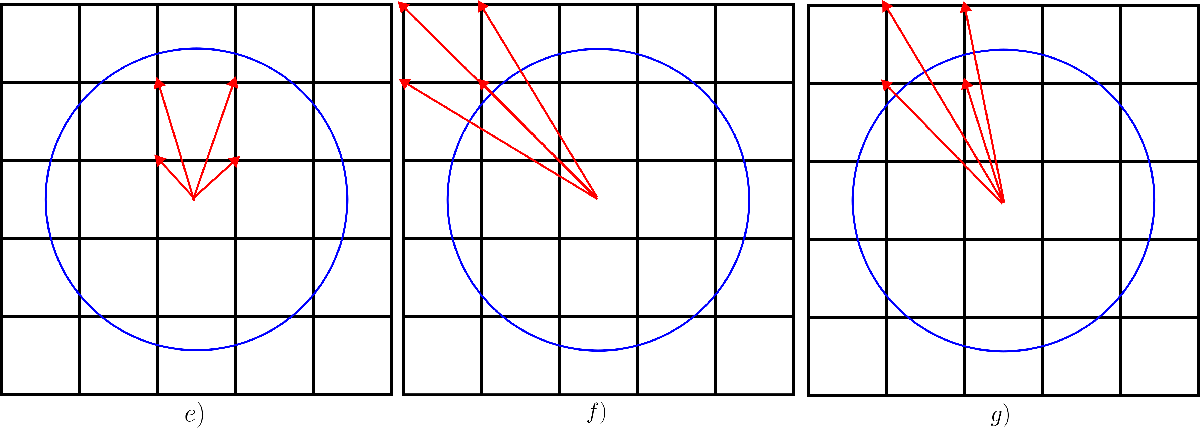

We will handle interfacial cells by breaking them up into a small sub-grid of cells. For example, in this case there are 40 cells in $x$ and 40 cells in $y$. The same condition will be applied to these interfacial cells, and if they fall within equation $(\mathcal{a})$, a volume fraction equivalent to $\frac{1}{40^2}$ will be added to that cell. The following code executes this implementation.

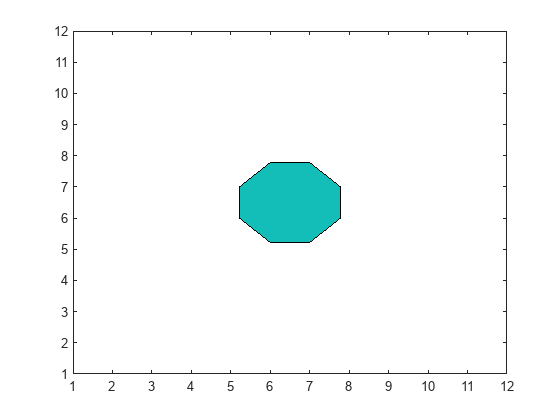

%% Initialize variables

xe = 1.0; % Domain length in x
ye = 1.0; % Domain length in y

dx = 1/10; %2*r/CPD; % Cell size x
dy = 1/10; %2*r/CPD; % Cell size y

nx = xe/dx; % Number of cells in x
ny = ye/dx; % Number of cells in y

f = zeros(ny+2,nx+2); % fluid volume fraction

r = 0.15; % Circle radius

xCent = 0.5; % Circle x-coordinate
yCent = 0.5; % Circle y-coordinate

for i=2:nx+1
    for j=2:ny+1
        tx =(i-2)*dx; % x value(left)
        ty =(j-2)*dy; % y value(bottom)
        txp =(i-2)*dx + dx; % x value(right)
        typ =(j-2)*dy + dy; % y value(top)
        
        % Why are we using max? It is used because we could be evaluating a
        % point on either side of the circle. So, to ensure all corners are
        % within our condition, we must evaluate the maximum.
        if max((tx-xCent)^2,(txp-xCent)^2) +  max((ty-yCent)^2,(typ-yCent)^2) <= r^2
            f(j,i) = 1.0;
        elseif min((tx-xCent)^2,(txp-xCent)^2) +  min((ty-yCent)^2,(typ-yCent)^2) > r*r
            f(j,i) = 0.0;
        else
            for l=1:40
                for m=1:40
                    txx =(i-2)*dx +(l-1)*dx/40;
                    tyy =(j-2)*dy +(m-1)*dy/40;
                    txxp =(i-2)*dx + l*dx/40;
                    tyyp =(j-2)*dy + m*dy/40;

                    if max((txx-xCent)^2,(txxp-xCent)^2) + max((tyy-yCent)^2,(tyyp-yCent)^2) < r^2
                        f(j,i) = f(j,i) +(1/40)*(1/40);
                    end
                end
            end
        end
    end
end

% Contour plot of volume fraction field, with contour line at 0.5
cl = [0.5 0.5];
contourf(f,cl)

As you can see, our fluid drop does not quite look like a circle. This is because the mesh resolution is very coarse, and the contour plot is interpolating an approximate interface for the volume fraction field. 

Below are the true values of the volume fraction field. At this point, they do not tell us anything about how our interface is reconstructed. 

f

f =          0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0    0.0038    0.3612    0.3612    0.0038         0         0         0         0
         0         0         0         0    0.3612    1.0000    1.0000    0.3606         0         0         0         0
         0         0         0         0    0.3612    1.0000    1.0000    0.3606         0         0         0         0
         0         0         0         0    0.0038    0.3606    0.3606    0.0038         0         0         0         0
         0         0        

To see a more resolved field, change $dx=dy=\frac{1}{100}$ and **Run **the above code again. After visualizing the more refined field, change $dx=dy=\frac{1}{10}$. This will make geometric reconstruction and flux calculation more digestible.

### Flux calculation

Let us design a method for determining the flux across a cell face, given a volume fraction field $f$and a velocity field $\vec{U}$. The method will perform interface advection in a split scheme, which first advects the fluid in the x-direction and then advects the fluid in the y-direction. In the next time step, the y-direction advection occurs first. This is also known as **direction split VOF**. However, the first step is to perform geometric reconstruction, and determine which coordinate direction the interface is parallel with. A single VOF advection is also possible.

#### Geometric reconstruction

As seen from the SLIC reconstruction, there are four options. We are going to choose the interface to always be normal with the direction of flux advection. In this scheme, if the interface is being advected in the x-direction, the SLIC will be vertical. Likewise, for interface advection in the y-direction, the SLIC will be horizontal. The interface will have an outward facing normal, based on a three-cell stencil: positive to the east, negative to the west, positive to the north, and negative to the south. If the volume fraction of a cell is equal to one, the normal value will be zero.

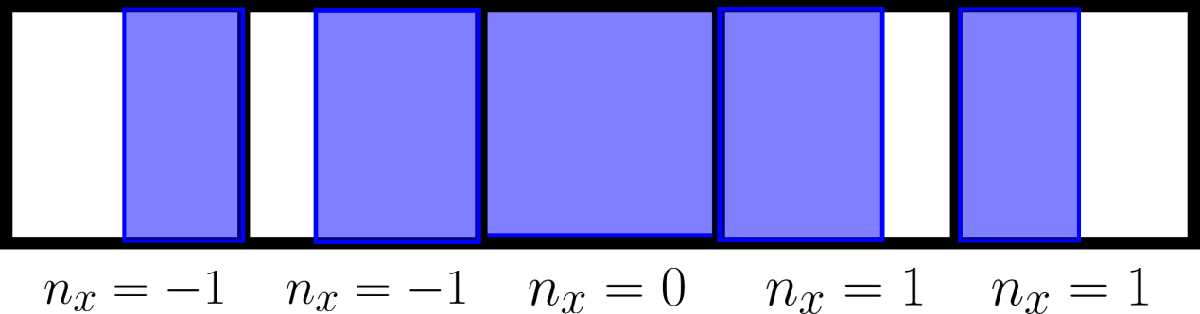

The code for the algorithm utilizies information about the existing volume fraction. 

norm = zeros(ny+2,nx+2);
for i=2:nx+1
    for j=2:nx+1
        if f(j,i) == 1.0 || f(j,i) == 0.0
            norm(j,i) = 0;
        elseif f(j,i+1) < f(j,i-1)
            norm(j,i) = 1;
        elseif f(j,i+1) > f(j,i-1)
            norm(j,i) = -1;
        else
            norm(j,i) = 0;
        end
    end
end
norm

norm =      0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    -1    -1     1     1     0     0     0     0
     0     0     0     0    -1     0     0     1     0     0     0     0
     0     0     0     0    -1     0     0     1     0     0     0     0
     0     0     0     0    -1    -1     1     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0


Compare the above normal values to the volume fraction field. **Do these normal values coreespond to how we wanted to describe the volume fraction field? **This normal now acts as an indicator to determine how the flux is calculated. Now, let's formulate an algorithm for calculating the flux. 

#### Flux 

To start, let's compute the flux for $n_{x_{j,i}} =1$, and a velocity $u_{j,i} = -1$. Following the same convention as the flow solver, the flux at cell(j, i) is going to be to the minus side(it is a face centered value on a staggered grid). In the algorithm, a flux is only calculated at a face(j,i), if that cell is donating volume.

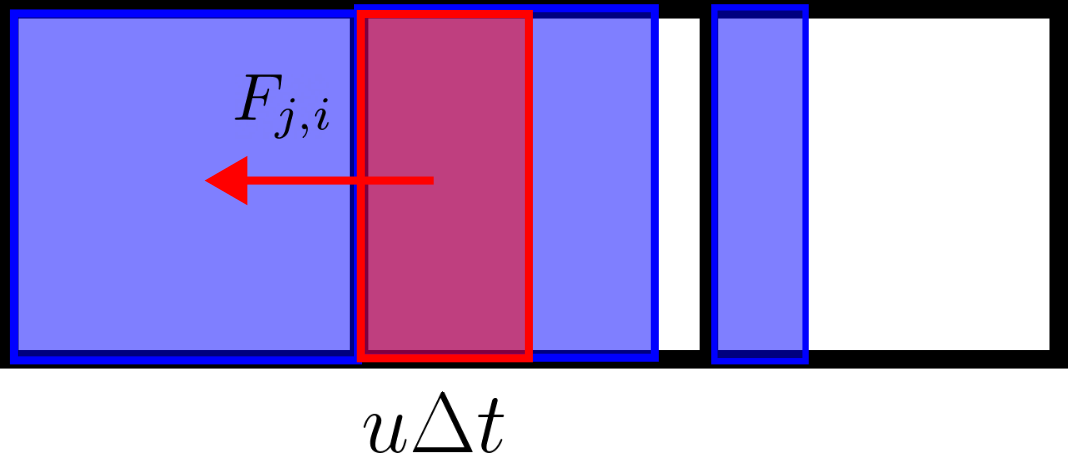

In this example, the flux being donated is aligned with the volume fraction field on the left face. This indicates that the flux is going to be:


$$F_{j,i} = \begin{cases} -f_{j,i} \Delta x, & \text{if} &f_{j,i}\Delta x \leq |u_{j,i} \Delta t| \\ u_{j,i} \Delta t, & \text{otherwise}\end{cases}$$


** Why is the flux a conditional statement?**

The flux is conditional because there is a maximum amount of fluid which can be donated through the left face. The amount of fluid being fluxed through the left face is always equal to $u_{j,i}\Delta t$. However, we are not interested in the void fraction of fluid, so the amount of $f$ needs to be computed. The conditional statement appears because it's possible for $f_{j,i}\Delta x < |u_{j,i} \Delta t |$ . If that is the case, then all the fluid we are tracking is fluxed through the left face. Keep in mind the importance of the sign of the flux. **Run **the following code to calculate the flux.

% Initializing flux, u velocity, and timestep
flux = zeros(ny+2,nx+2);
u = -ones(ny+2,nx+2);
dt = 0.3*dx;

% Computing fluxes
for i=2:nx
    for j=2:ny
        if norm(j,i) == 1 || norm(j,i) == 0
            if u(j,i) < 0
                if abs(u(j,i)*dt/dx) >= f(j,i)
                    flux(j,i) = -f(j,i)*dx;
                else
                    flux(j,i) = u(j,i)*dt;
                end
            end
        end
    end
end
f(4:ny,4:nx) % Original volume fraction field

ans =          0         0         0         0         0         0         0
         0    0.0038    0.3612    0.3612    0.0038         0         0
         0    0.3612    1.0000    1.0000    0.3606         0         0
         0    0.3612    1.0000    1.0000    0.3606         0         0
         0    0.0038    0.3606    0.3606    0.0038         0         0
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0


flux(4:ny,4:nx)/dx % Computed flux(x-dir)

ans =          0         0         0         0         0         0         0
         0         0         0   -0.3000   -0.0038         0         0
         0         0   -0.3000   -0.3000   -0.3000         0         0
         0         0   -0.3000   -0.3000   -0.3000         0         0
         0         0         0   -0.3000   -0.0038         0         0
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0


**Analyze the output of the flux calculated above; is it correct?**

Notice above that not every face has a flux calculated. So far, the for loop only solves for flux under a limited set of conditions. To find the flux at other cells, more conditions need to be accounted for. Let's determine the fluxes when $u_{j,i+1} = 1$.

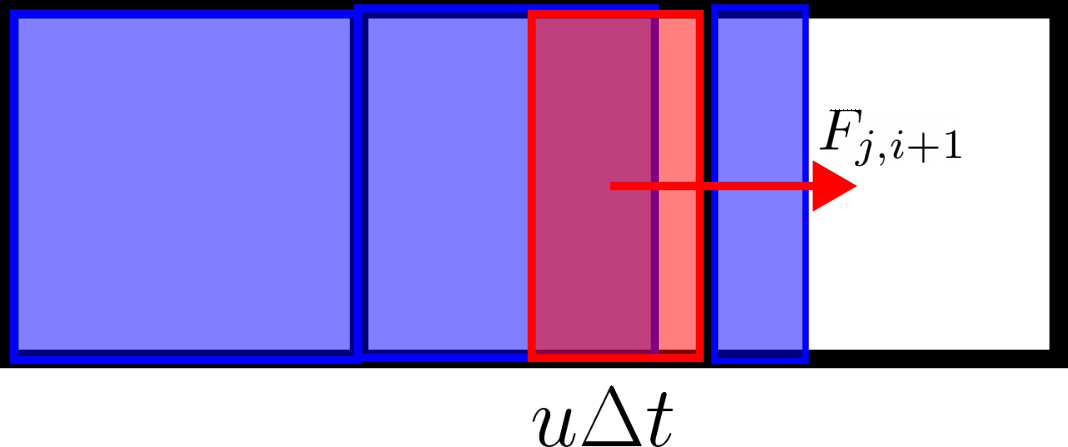

Following the same convention, the flux at the $(j, i+1)$ face will be the right face.


$$F_{j,i+1} = \begin{cases} f_{j,i}\Delta x + u_{j,  i+1}\Delta t - \Delta x, & \text{if} &f_{j,i}\Delta x + u_{j,i+1}\Delta t > \Delta x \\ 0, & \text{otherwise}\end{cases}$$


Now, the overlap between the advected flux and fluid must be calculated. In the other case, it was more obvious since the flux and fluid were aligned at the same face. However, for this case, we know the advected flux and the available fluid for fluxing overlap if they add up to more than the size of a cell. Otherwise, they are not overlapping, and no fluid is being donated.

% Initializing flux and u velocity
flux = zeros(ny+2,nx+2);
u(:,:) = ones;

% Computing fluxes
for i=2:nx
    for j=2:ny
        if norm(j,i) == 1 || norm(j,i) == 0
            if u(j,i) < 0
                if abs(u(j,i)*dt/dx) >= f(j,i)
                    flux(j,i) = -f(j,i)*dx;
                else
                    flux(j,i) = u(j,i)*dt;
                end
            end
            if u(j,i+1) > 0
                if f(j,i)*dx + u(j, i+1)*dt > dx
                    flux(j,i+1) = f(j,i)*dx + u(j,i+1)*dt - dx;
                else
                    flux(j,i+1) = 0.0;
                end
            end
        end
    end
end
f(4:ny,4:nx) % Original volume fraction field

ans =          0         0         0         0         0         0         0
         0    0.0038    0.3612    0.3612    0.0038         0         0
         0    0.3612    1.0000    1.0000    0.3606         0         0
         0    0.3612    1.0000    1.0000    0.3606         0         0
         0    0.0038    0.3606    0.3606    0.0038         0         0
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0


flux(4:ny,4:nx)/dx % Computed flux(x-dir)

ans =          0         0         0         0         0         0         0
         0         0         0         0         0         0         0
         0         0         0    0.3000    0.3000         0         0
         0         0         0    0.3000    0.3000         0         0
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0
         0         0         0         0         0         0         0


 **Notice which cell faces contain fluxes and relate that to their volume fractions and outward facing normal.**

Following the same procedure as above, we can construct the flux values when $n_x = -1$ and $u_{j,i} = -1$

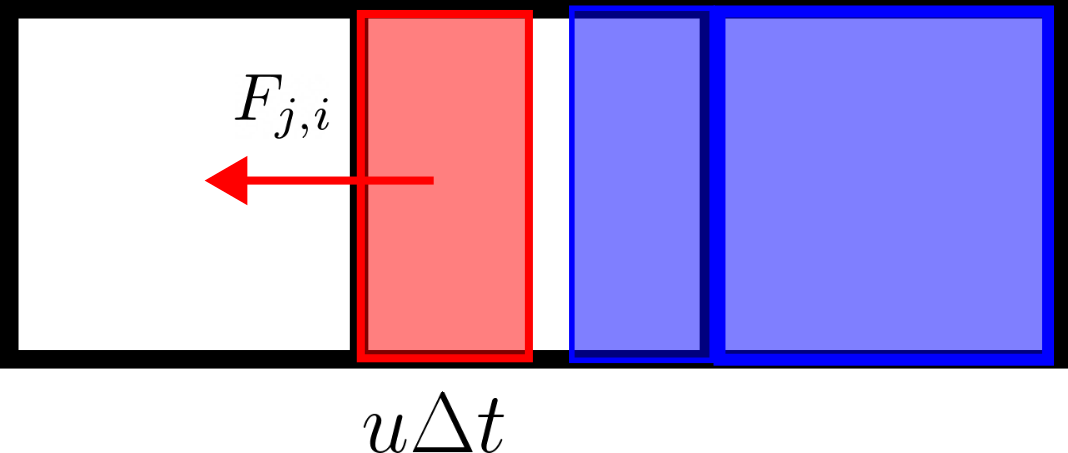


$$F_{j,i} = \begin{cases} f_{j,i}\Delta x + |u_{j,  i+1}\Delta t| - \Delta x, & \text{if} &f_{j,i}\Delta x + |u_{j,i+1}\Delta t| > \Delta x \\ 0, & \text{otherwise}\end{cases}$$


The conditions are almost identical. Here absolute value signs are included since the velocity is negative. Now, the final flux when $u_{j,i+1} = 1$:

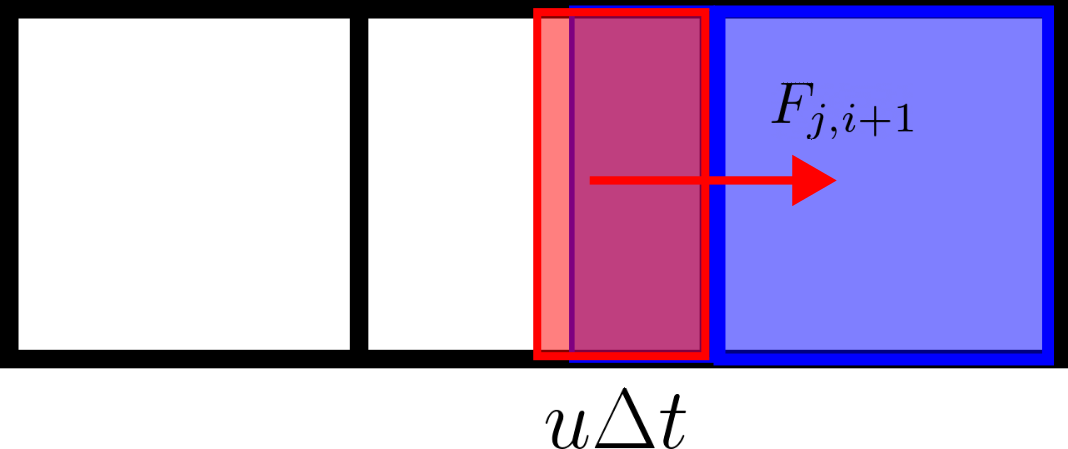


$$F_{j,i+1} = \begin{cases}  f_{j,i} \Delta x, & \text{if} &f_{j,i}\Delta x \leq u_{j,i+1} \Delta t \\ u_{j,i} \Delta t, & \text{otherwise}\end{cases}$$


The above equations also hold true for calculating the flux in the y-direction. Using these fluxes and following equation $(\mathcal{T})$, the volume fraction field can be updated. However, there is something we have yet to consider. In all these cases, the velocity field is divergence free within a single advection direction. Taking the divergence in x or taking the divergence in y would both yield zero. 


$$\frac{\partial u}{\partial x} = \frac{\partial v}{\partial y} = 0$$


In a natural flow field this is not the case. It is possible to have divergence in x and divergence in y, with the total being zero.


$$\frac{\partial u}{\partial x} + \frac{\partial v}{\partial y} = 0$$


 **What are the implications to the volume fraction field using a direction split VOF method?**

If there is a divergence in either the u or v velocity field, it is possible when updating the volume fractions to achieve values greater than one. Since this is a directional split method, if this occurs in the first sweep, the next sweep will not know how to deal with volume fractions greater than one. As you can see, that is not baked into the mathematical formulation. To handle such cases, a cell volume allowance is calculated for each directional sweep. In an x-directional sweep, the following equations are:


$$\tilde{f_{j,i}} = f_{j,i}^n \Delta V_{j,i}^n - \frac{(F_R - F_L)}{\Delta x}$$



$$\Delta V_{j, i}^{n+1/2} = \Delta V^n_{j,i} - \Delta t \Delta y (u_{j,i+1} - u_{j,i})$$



$$f^{n+1/2}_{j,i} = \frac{\tilde{f_{j,i}}}{\Delta V^{n+1/2}_{j,i}}$$


Where $\Delta V_{j, i}^{n}$ is the cell volume at the beginning of each time step, $\Delta V_{j, i}^{n+1/2}$ is the volume allowance, and $f^{n+1/2}_{j,i}$ is the volume fraction after a single sweep. In a y-directional sweep, an equivalent set of steps is performed. Once both sweeps are completed, $\Delta V_{j, i}^{n}$ should be equivalent to the original.

###  Exercise 1(difficult)

- **Run** the following code. You will see the droplet being advected in the x-direction on a really coarse grid. Change $dx = dy = \frac{1}{100}$, and **Run **the code to see the advection take place on a finer mesh. A short video will play at the bottom of the code.

- Set $dx = dy = \frac{1}{10}$. Also, change $u = 0$, and $v = \text{maxVelocity}$. Change the "big for loop" to iterate to one, instead of t_steps. Go to the section of the code under "case y". There will be 8 lines of code with the flux calculation commented out. Try to develop equations for the flux in the y direction. The formulation is exactly the same as the x-direction flux.

 **Hint: **Output the volume fraction field, the normals, and the fluxes to explicitly see the values being calculated. Focus on each case independent of the others. This will allow you to see if your code has run as intended. If you get stuck, you can open the slic.m file for the answers.

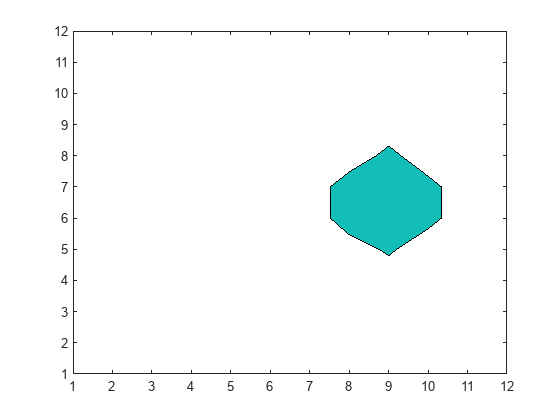

% Initialize variables

xe = 1.0; % Domain length in x
ye = 1.0; % Domain length in y

dx = 1/10; %2*r/CPD; % Cell size x
dy = 1/10; %2*r/CPD; % Cell size y

nx = xe/dx; % Number of cells in x
ny = ye/dx; % Number of cells in y

f = zeros(ny+2,nx+2); % fluid volume fraction
u = zeros(ny+2,nx+2); % u velocity component
v = zeros(ny+2,nx+2); % v velocity component

maxVelocity = 1.0;
u(:,:) = maxVelocity;
v(:,:) = 0.0; 

r = 0.15; % Circle radius

xCent = 0.5; % Circle x-coordinate
yCent = 0.5; % Circle y-coordinate

for i=2:nx+1
    for j=2:ny+1
        tx =(i-2)*dx; % x value(left)
        ty =(j-2)*dy; % y value(bottom)
        txp =(i-2)*dx + dx; % x value(right)
        typ =(j-2)*dy + dy; % y value(top)

        if max((tx-xCent)^2,(txp-xCent)^2) +  max((ty-yCent)^2,(typ-yCent)^2) <= r^2
            f(j,i) = 1.0;
        elseif min((tx-xCent)^2,(txp-xCent)^2) +  min((ty-yCent)^2,(typ-yCent)^2) > r*r
            f(j,i) = 0.0;
        else
            for l=1:40
                for m=1:40
                    txx =(i-2)*dx +(l-1)*dx/40;
                    tyy =(j-2)*dy +(m-1)*dy/40;
                    txxp =(i-2)*dx + l*dx/40;
                    tyyp =(j-2)*dy + m*dy/40;

                    if max((txx-xCent)^2,(txxp-xCent)^2) + max((tyy-yCent)^2,(tyyp-yCent)^2) < r^2
                        f(j,i) = f(j,i) +(1/40)*(1/40);
                    end
                end
            end
        end
    end
end

volume = ones(ny+2,nx+2)*dx*dy;
v_tilde = zeros(ny+2,nx+2);

dt = 0.3*dx*maxVelocity;
t_steps = round(0.25/abs(maxVelocity)/dt);

plt = 0;
pldt = round(t_steps/10);

% Big for loop
for t=1:t_steps
    % Set directional sweep
    if mod(t,2) == 0
        direction = 'x';
    else
        direction = 'y';
    end
    
    counter = 0;

    while counter < 2
        norm = zeros(ny+2,nx+2);
        flux = zeros(ny+2,nx+2);
        f_old = f;
        
        switch direction
            case 'x'
                % Calculate norm and v_tilde
                for i=2:nx+1
                    for j=2:nx+1
                        if f(j,i) == 1.0 || f(j,i) == 0.0
                            norm(j,i) = 0;
                        elseif f(j,i+1) < f(j,i-1)
                            norm(j,i) = 1;
                        elseif f(j,i+1) > f(j,i-1)
                            norm(j,i) = -1;
                        else
                            norm(j,i) = 0;
                        end
                        
                        v_tilde(j,i) = volume(j,i) - dt*dy*(u(j,i+1) - u(j,i));
                    end
                end
                
                % Calculate flux
                for i=2:nx
                    for j=2:ny
                        if norm(j,i) == 1 || norm(j,i) == 0
                            if u(j,i) < 0
                                if abs(u(j,i)*dt/dx) >= f(j,i)
                                    flux(j,i) = -f(j,i)*dx;
                                else
                                    flux(j,i) = u(j,i)*dt;
                                end
                            end
                            if u(j,i+1) > 0
                                if f(j,i)*dx + u(j,i+1)*dt > dx
                                    flux(j,i+1) = f(j,i)*dx + u(j,i+1)*dt - dx;
                                else
                                    flux(j,i+1) = 0.0;
                                end
                            end
                        elseif norm(j,i) == -1
                            if u(j,i+1) > 0
                                if u(j,i+1)*dt/dx >= f(j,i)
                                    flux(j,i+1) = f(j,i)*dx;
                                else
                                    flux(j,i+1) = u(j,i+1)*dt;
                                end
                            end
                            if u(j,i) < 0
                                if f(j,i)*dx + abs(u(j,i)*dt) > dx
                                    flux(j,i) = dx - f(j,i)*dx - abs(u(j,i)*dt);
                                else
                                    flux(j,i) = 0.0;
                                end
                            end
                        end
                    end
                end
                
                % Update f
                for i=2:nx
                    for j=2:ny
                        f(j,i) = f_old(j,i)*volume(j,i) +(flux(j,i) - flux(j,i+1))/dx*volume(j,i);
                        f(j,i) = f(j,i)/v_tilde(j,i);
                    end
                end
                volume = v_tilde;

            case 'y'
                % Calculate norm
                for i=2:nx+1
                    for j=2:nx+1
                        if f(j,i) == 1.0 || f(j,i) == 0.0
                            norm(j,i) = 0;
                        elseif f(j+1,i) < f(j-1,i)
                            norm(j,i) = 1;
                        elseif f(j+1,i) > f(j-1,i)
                            norm(j,i) = -1;
                        else
                            norm(j,i) = 0;
                        end

                        v_tilde(j,i) = volume(j,i) - dt*dx*(v(j+1,i) - v(j,i));
                    end
                end
                
                % Calculate flux(Write the code in this section)
                % Uncomment the flux,and write the code for flux
                % computation in the y-direction
                for i=2:nx
                    for j=2:ny
                        if norm(j,i) == 1 || norm(j,i) == 0
                            if(v(j,i) < 0)
                                if abs(v(j,i)*dt/dy) >= f(j,i)
                                    %flux(j,i) = 
                                else
                                    %flux(j,i) = 
                                end
                            end
                            if v(j+1,i) > 0
                                if(f(j,i)*dy + v(j+1,i)*dt > dy)
                                    %flux(j+1,i) = 
                                else
                                    %flux(j+1,i) = 
                                end
                            end
                        elseif norm(j,i) == -1
                            if v(j+1,i) > 0
                                if v(j+1,i)*dt/dy >= f(j,i)
                                    %flux(j+1,i) = 
                                else
                                    %flux(j+1,i) = 
                                end
                            end
                            if v(j,i) < 0
                                if f(j,i)*dy + abs(v(j,i)*dt) > dy
                                    %flux(j,i) = 
                                else
                                    %flux(j,i) = 
                                end
                            end
                        end
                    end
                end
                
                % Update f
                for i=2:nx
                    for j=2:ny
                        f(j,i) = f_old(j,i)*volume(j,i) +(flux(j,i) - flux(j+1,i))/dy*volume(j,i);
                        f(j,i) = f(j,i)/v_tilde(j,i);
                    end
                end
                volume = v_tilde;
        end

        counter = counter + 1;
        if direction == 'x'
            direction = 'y';
        else
            direction = 'x';
        end
    end

    % Plotting
    if plt == pldt || t == int16(t_steps-1)
        cl = [0.5 0.5];
        contourf(f,cl)
        pause(0.2)
        plt = 0;
    end
    plt = plt+1;
end

###  Exercise 2

The goal of this exercise is to evaluate the SLIC scheme's performance and understand why it may perform well or poorly, depending on the flow field. In the following code, there are three different test cases([all various benchmarks taken from literature](https://www.sciencedirect.com/science/article/abs/pii/S0045793010000861)). The tests include solid body translation, solid body rotation, and flow in a vortex field(shear flow).

- Open the file and run each section of benchmark cases.

- Assess the performance of the SLIC advection method. Was there volume loss or gain? How close is the final position of the drop to the exact?

- Does it perform well or poorly in any particular case? If so, why?

- Is the performance of the method improved with mesh refinement?

% open("exercise/slic.m")

###  Exercise 3

Write a new function to initialize an arbitrarily shaped geometry and set a new velocity field to advect the fluid.

- Write a function similar to initDrop, but instead of initializing a circle, initialize a square.

- Perform the same test cases as exercise 2, but for the square. Does it perform better or worse?

- Write a new velocity field(your choice) to advect the square uniquely.

###  Exercise 4(advanced)

Improve the SLIC method, using the [Hirt and Nichols](https://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.413.7358&rep=rep1&type=pdf) reconstruction scheme. In our scheme, a three cell stencil parallel to the advection direction was used to determine the interface normal. In Hirt and Nichols, a nine-cell stencil is used. As a result, advection can occur in the x direction with a interface normal that is perpendicular. This adds more complexity the flux calculation, but can achieve better performance.

- Write a method for calculating the interface normal.

- In the SLIC function, assess which normal component is greater. If it is x, then the interface is reconstructed such that its normal is in x.

- Revise the existing if statements in the SLIC function to depend on these new normal values.

- Write a new if statement for x and y direction fluxes for when the normal is not parallel to the flux direction.

- Test the method. Does it perform better in simple translation cases? What about shear flow? 

**Next section:**

The following section introduces fluid structure interaction using immersed boundary and direct forcing methods. The following code opens up the final teaching module in this course.

% open("../fluidStructureInteraction/FSI_teachingModule.mlx")